# .100:1 DC Motor Characterization

## 1. Create test data

maxPWM = 255.00;% maximum duty cycle
incrPWM = 1;% PWM increment
PWMcmdRaw = (-maxPWM:incrPWM:maxPWM)';% column vector of duty cycles from -1 to 1

## 2. Create and initialize device objects

clear a dcm carrier enc% delete existing device objects

a = arduino;
carrier = addon(a,'Arduino/MKRMotorCarrier');
dcm = dcmotor(carrier,4);

enc = rotaryEncoder(carrier,2);
resetCount(enc);

## 3. Measure raw motor speed for each PWM command

speedRaw = zeros(size(PWMcmdRaw));% Preallocate vector for speed measurements

dcm.DutyCycle = 0;
start(dcm)% turn on motor

for ii = 1:length(PWMcmdRaw)
    resetCount(enc);
    
    dcm.DutyCycle = PWMcmdRaw(ii);
    pause(1)% wait for steady state
    
    speedRaw(ii) = -((readSpeed(enc)/60)*12*100.37); % read speed (cts/s)
end

stop(dcm)% turn off motor

## 4. Post-process and save data

idx = (diff(speedRaw) > 0);% find indices where vector is increasing

speedMono = speedRaw(idx);% Keep only increasing values of speed
PWMcmdMono = PWMcmdRaw(idx);% Keep only corresponding PWM values

PWMcmdMono(speedMono == 0) = 0;% enforce zero power for zero speed

save motorResponse PWMcmdMono speedMono% save post-processed measurements

## 5. Graph raw and post-processed data

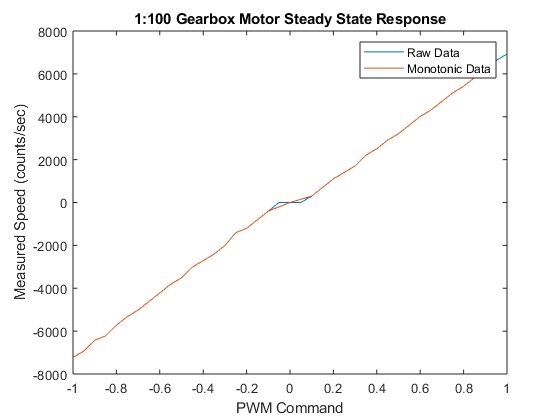

plot(PWMcmdRaw,speedRaw)% raw speed measurements
hold on
plot(PWMcmdMono,speedMono)% non-monotonic measurements filtered out

title('1:100 Gearbox Motor Steady State Response')
xlabel('PWM Command')
ylabel('Measured Speed (counts/sec)')
legend('Raw Data','Monotonic Data')

## 6. Delete device objects

clear a dcm carrier enc

*Copyright 2018 The MathWorks, Inc.*